clear; clf; close all;

robot = RA_CreateRobot(false, true);

--------------------
Robot: (3 bodies)

 Idx    Body Name    Joint Name    Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------    ----------    ----------    ----------------   ----------------
   1        link1        joint1      revolute             base(0)   link2(2)  
   2        link2        joint2      revolute            link1(1)   tool(3)  
   3         tool           fix         fixed            link2(2)   
--------------------


robot_home = homeConfiguration(robot)';

RA_ForwardKinematics(robot, deg2rad([90 0]), false)

ans =     0.0000   -0.0000    1.0000    0.0000
    0.0000   -1.0000   -0.0000    0.0000
    1.0000    0.0000   -0.0000    1.4000
         0         0         0    1.0000


[angles, sol] = RA_InverseKinematics(robot, [0.65 0.0 0.85], [-0.89 1.57])

angles =    -0.0670
    1.4202


sol = struct with fields:
           Iterations: 1500
    NumRandomRestarts: 120
        PoseErrorNorm: 3.1416
             ExitFlag: 2
               Status: 'best available'


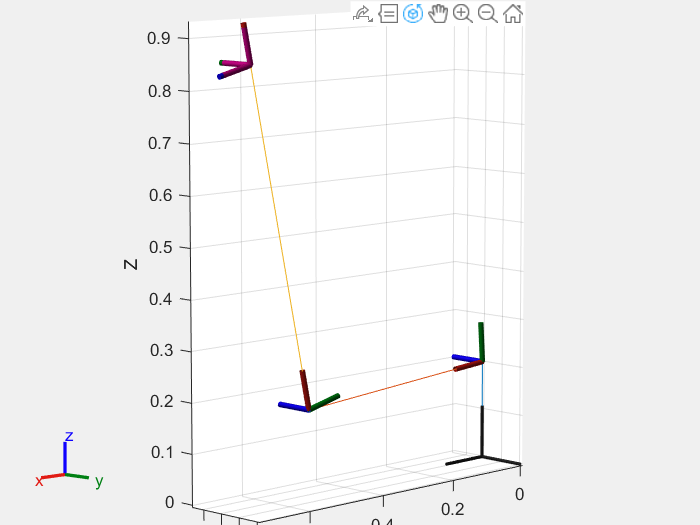

ans =     0.2159   -0.0000    0.9764    0.6500
    0.0000   -1.0000   -0.0000    0.0000
    0.9764    0.0000   -0.2159    0.8500
         0         0         0    1.0000


RA_ForwardKinematics(robot, angles, true)

wpts = [0.0 0.85 0.85 -0.65 0.53;
        0.0 0.0  0.0  0.0 0.0;
        1.4 0.35 0.85 0.85 0.42];
tpts = [3 6 9 12 15];

initialGuess = deg2rad([90 0]);
[C, T, q, qd, qdd] = RA_GenerateJointTrajectory(robot, wpts, tpts, initialGuess');

## Verification

RA_PlotTrajectory(robot, q, T, wpts, tpts);

RA_PlotTrajectory3D(robot, q ,wpts);


RA_AnimateRobotTrajectory(robot, q);



## Visualization

% % Visualize the results
% figure(1);
% % Plot joint positions
% subplot(3,1,1);
% plot(linspace(tpts(1), tpts(end), size(q,2)), q');
% title('Joint Positions');
% xlabel('Time (s)');
% ylabel('Joint Angle (rad)');
% legend('Joint 1', 'Joint 2');
% grid on;
% 
% % Plot joint velocities
% subplot(3,1,2);
% plot(linspace(tpts(1), tpts(end), size(qd,2)), qd');
% title('Joint Velocities');
% xlabel('Time (s)');
% ylabel('Angular Velocity (rad/s)');
% grid on;
% 
% % Plot joint accelerations
% subplot(3,1,3);
% plot(linspace(tpts(1), tpts(end), size(qdd,2)), qdd');
% title('Joint Accelerations');
% xlabel('Time (s)');
% ylabel('Angular Acceleration (rad/s²)');
% grid on;
% 
% % Visualize the trajectory in 3D space
% figure(2);
% % Preallocate for end-effector positions
% numPoints = size(q, 2);
% endEffectorPositions = zeros(3, numPoints);
% 
% % Calculate end-effector position at each time step
% for i = 1:numPoints
%     % Get the end-effector transform at this configuration
%     endTransform = RA_ForwardKinematics(robot, q(:, i), false);
%     % Extract the position (last column, first 3 rows)
%     endEffectorPositions(:, i) = endTransform(1:3, 4);
% end
% 
% % Plot the waypoints and the trajectory
% plot3(wpts(1,:), wpts(2,:), wpts(3,:), 'ro', 'MarkerSize', 10, 'LineWidth', 2);
% hold on;
% plot3(endEffectorPositions(1,:), endEffectorPositions(2,:), endEffectorPositions(3,:), 'b-', 'LineWidth', 2);
% grid on;
% title('Robot End-Effector Trajectory');
% xlabel('X (m)');
% ylabel('Y (m)');
% zlabel('Z (m)');
% legend('Waypoints', 'Trajectory');
% 
% % Animate the robot movement (optional)
% figure(3);
% title('Robot Motion Animation');
% for i = 1:10:numPoints
%     % Show robot at different configurations along the trajectory
%     config = homeConfiguration(robot);
%     for j = 1:length(config)
%         config(j) = q(j, i);
%     end
%     show(robot, config, 'PreservePlot', false);
%     drawnow;
%     pause(0.1);
% end